clear all
clf
% Bilderna sökväg
%imagePath = '../HDR/ImagesSmall/';
%imagePath = '../HDR/Near_3/';
imagePath = '../HDR/Far_3/';

% Alla tiff-filer i mappen
imageList = dir(fullfile(imagePath, '*.tiff'));
imageAmount = numel(imageList);

%Första bilden
firstImage = imread(fullfile(imagePath, imageList(1).name));

% Hämta storleken på den första bilden
[row, col, channel] = size(firstImage);

%Initialize allImages
allImages = zeros(row, col, channel, imageAmount,'uint8');

%Sparar alla bilder i allImages
for i = 1:imageAmount
    allImages(:,:,:,i) = imread(fullfile(imagePath, imageList(i).name));
    %figure;
    %imshow(allImages(:,:,:,i));
end

B = zeros(imageAmount,1);

% ImagesSmall
%  B(1) = 1/4000;
%  B(2) = 1/2000; 
%  B(3) = 1/1000;
%  B(4) = 1/500;
%  B(5) = 1/250;
%  B(6) = 1/125;
%  B(7) = 1/60;
%  B(8) = 1/30;
%  B(9) = 1/15;
%  B(10) = 1/6;
%  B(11) = 1/3;
%  B(12) = 0.6;
%  B(13) = 1.3;

% Near_3
%  B(1) = 1/30; % 8
%  B(2) = 1/6; % 10
%  B(3) = 0.6; % 12

% Far_3
 B(1) = 1/250; % 5
 B(2) = 1/15; % 9
 B(3) = 1.3; % 13

B = log(B);
w = hat(0:255);
%w = linspace(0, 255, 256); %Testa utan w-hat
lambda = 100;

paintRed = 0; % Boolean för att visa bild med valda positioner i rött, eller inte

sampleAmount = 500; % Per image

pixelSamples = sampleAmount*imageAmount % Total amount

pixelSamples = 1500


[Z_red, Z_green, Z_blue]  = zMake_slump(allImages, imageAmount, pixelSamples, row, col, paintRed);

    "Slump!"




%"Global" linspace:
%[Z_red, Z_green, Z_blue]  = zMake_pick(allImages, imageAmount, sampleAmount, pixelSamples, paintRed);

% "Local" linspace - diskuteras ej, inga bilder härifrån:
%[Z_red, Z_green, Z_blue]  = zMake_pick2(allImages, imageAmount, sampleAmount, pixelSamples, paintRed);

% TILLÄGG?:
% UTAN SORTERING: sampleAmount stycken pixelvärden från bild 1 kommer först, sen från bild 2, etc.
% MED SORTERING: alla pixelvärden sorteras i stigande ordning. Enligt observationer från "red"-bilderna.
% Gör ingen skillnad i resultat, så bortkommenterad - vet ej om tekniskt korrekt.
% Z_red = sort(Z_red);
% Z_green = sort(Z_green);
% Z_blue = sort(Z_blue);

%Beräknar g-kurvan och log(E) med funtionen gsolve
[gCurveRed,~] = gsolve(Z_red,B,lambda,w);
[gCurveGreen,~] = gsolve(Z_green,B,lambda,w);
[gCurveBlue,~] = gsolve(Z_blue,B,lambda,w);

% Titta på luminans-histo. från valda pixlar, för både slump (ZZ1) och pick ("global", ZZ):
% ZZ1 = ((Z_red1 + Z_green1 + Z_blue1))/3;
% ZZ1 = ZZ1(:);
% 
% ZZ = ((Z_red + Z_green + Z_blue))/3;
% ZZ = ZZ(:);
% 
% figure;               
% histogram(ZZ1);
% 
% figure;               
% histogram(ZZ);

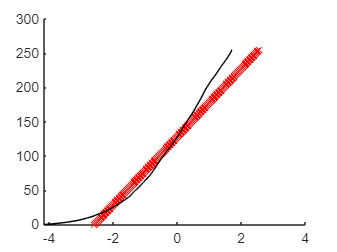

gCurve2 = makegfun;
y = linspace(0, 255, 256)';

figure;
hold on;
plot(gCurveRed, y, 'rx');
plot(gCurve2(:,1), y, 'k'); %Facit

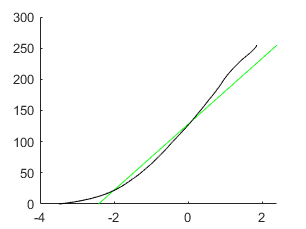


figure;
hold on;
plot(gCurveGreen, y, 'g-');
plot(gCurve2(:,2), y, 'k'); %Facit

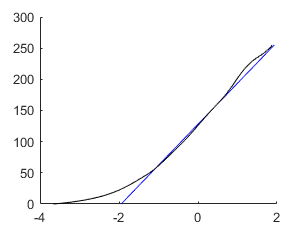


figure;
hold on;
plot(gCurveBlue, y, 'b-');
plot(gCurve2(:,3), y, 'k'); %Facit

% R-squared
rS_y = linspace(0, 255, 256);

r_rS_x = gCurveRed;
r_mdl = fitlm(r_rS_x, rS_y);

g_rS_x = gCurveGreen;
g_mdl = fitlm(g_rS_x, rS_y);

b_rS_x = gCurveBlue;
b_mdl = fitlm(b_rS_x, rS_y);

r_mdl.Rsquared.Ordinary

ans = 1.0000


g_mdl.Rsquared.Ordinary

ans = 1.0000


b_mdl.Rsquared.Ordinary

ans = 1.0000


(r_mdl.Rsquared.Ordinary + g_mdl.Rsquared.Ordinary + b_mdl.Rsquared.Ordinary)/3

ans = 1.0000

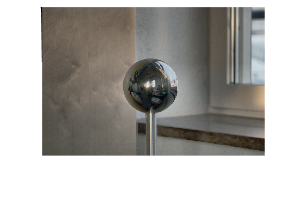

% RadianceMap och tone mapping - MATLABs egna, ba för se rimlighet

allImagesRed = squeeze(allImages(:,:,1,:));
allImagesGreen = squeeze(allImages(:,:,2,:));
allImagesBlue = squeeze(allImages(:,:,3,:));

imRed = createRadianceMap(allImagesRed, gCurveRed, w./127, B);
imGreen = createRadianceMap(allImagesGreen, gCurveGreen, w./127, B);
imBlue = createRadianceMap(allImagesBlue, gCurveBlue, w./127, B);

imRed = exp(imRed);
imGreen = exp(imGreen);
imBlue = exp(imBlue);

HDR = cat(3, imRed, imGreen, imBlue);
HDRTone = tonemap(HDR);
imshow(HDRTone)